# Open-loop behaviour of state-space models in MATLAB

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours and analysis. A common linear model type is the state-space model. 

This file focuses on how we can infer the expected open-loop behaviour of a state-space models, in both continuous and discrete time. There are significant overlaps with the transfer function based files in the toolbox (***transferfunctions_and_behaviours, step_responses_with_matlab***) and so the reader may like to look at those in parallel. It is also worth being familiar with the preceding files of`: `***statespace_models_from_tf_control101, tf_models_from_statespace_control101***.

Specifically here we show how to expose the core dynamics and remind the user how to make use of ***step.m. ***A discussion of phase diagrams comes in the resource:*** phase_plane_statespace_control101.***

Lots of code snippets are provided as examples of how MATLAB can be used and the intention is that readers can use these as exemplars and/or templates and change the models and scenarios for their own need.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, Ross Drummond, Lanlan Su (University of Sheffield) and Ruth Bars (Budapest University of Technology and Economics)                           

MAJOR CHANGE: Sections 4,5,6 added to give a complete demonstration of dyanmics behavious in state space. 

## Table of Contents

- Background on finding transfer functions from state-space models

- Core observation on behaviours

- Step responses with MATLAB

- Unforced response with MATLAB 

- Forced response with MATLAB

- General response with MATLAB

## 1. Background on finding transfer function models from state-space models

The earlier file ***tf_models_from_statespace_control101 ***showed how to find a transfer function model from a state-space model. This resource will take that background as read.

$\dot{X} =A\;X+B\;U;\;Y=C\;X+D\;U,\;$with state *X*, input *U* and output *Y*. 

Take Laplace transforms of every element in this model, thus:


$$X\left(s\right)={\left\lbrack s\;I-A\right\rbrack }^{-1} B\;U\left(s\right);\;\;\;Y\left(s\right)=\underset{G\left(s\right)}{\underbrace{\left(C{\left\lbrack s\;I-A\right\rbrack }^{-1} B+D\right)} \;} U\left(s\right)=G\left(s\right)U\left(s\right)$$


## 2 Core observation on behaviours

From this it will be clear that the transfer function equivalent has a denominator given by:


$$d\left(s\right)=\det \left(s\;I-A\right)$$


Readers will also be familiar with the fact that one can solve for the eigenvalues of a matrix using the formula


$$\det \left(\lambda I-A\right)=0$$


from which it is evident that the roots of *d(s)*, that is the poles, correspond to the eigenvalues of *A*.

**Remark:** Links between pole positions and ouput behaviour is explored in the file: ***transferfunctions_and_behaviours ***and thus is not repeated here.

One can validate this with some simple MATLAB commands comparing the eigenvalues with the poles.

disp('Section 2 below')

Section 2 below


A=[-0.8 0.1;0.2 -0.5];B=[1 3;2 0];C=[1 0;1 -1];D=[0 0; 0 0];
G=ss(A,B,C,D);
poles = pzmap(G)

poles =    -0.8562
   -0.4438


eigenvalues  = eig(A)

eigenvalues =    -0.8562
   -0.4438


## 3. Step responses with MATLAB

This section is deliberately concise as it largely replicates the file: ***step_responses_with_matlab ***

In simple terms, once one has defined a linear system object, whether this is transfer function based, state-space or indeed continuous-time or discrete-time, the MATLAB call statement is essentially the same as MATLAB determines the object type behind the scenes and then does the computations required. It also determines the system dimension and produces IO data for every input-output pairing.

### 3.1 Basic operation of step.m 

The simplest use of ***step.m*** is to allow MATLAB to take all the decisions, such as, for how long is the step response wanted, how many points shall I calculate the response at and so forth; to do this simply provide the model as shown below. This option produces a figure.  Change lines below to explore different systems.

disp('Below is Section 3.1')

Below is Section 3.1


A=[-1 -3;-1.2 -5];
B=[2;-1];
C=[1 1];
D=0;
G=ss(A,B,C,D);
poles_of_A=eig(A)

poles_of_A =    -0.2432
   -5.7568


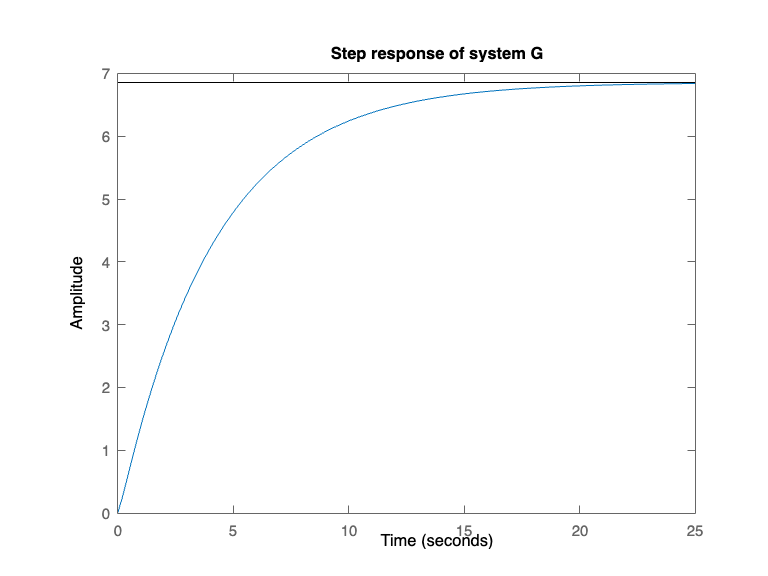

step(G)
title('Step response of system G')

### 3.2 Controlling the end time of the figure 

Should you want to insist on the time scale used for the step response, simply add a second input argument as a scalar, which is the end time.

disp('Below is Section 3.2')

Below is Section 3.2


endtimeG = 20

endtimeG = 20

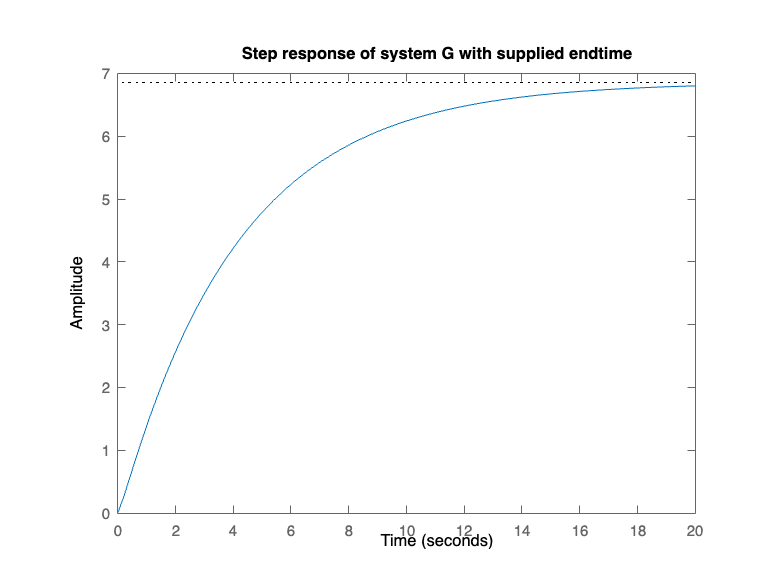

step(G,endtimeG)
title('Step response of system G with supplied endtime')

### 3.3 Collecting the numerical values of the step response

It may be that you want the numerical values of the step response. Typical code is shown here.

disp('Below is Section 3.3')

Below is Section 3.3


endtimeG = 1.2;
[yvaluesg, ytimesg] = step(G,endtimeG)

yvaluesg =          0
    0.0123
    0.0250
    0.0382
    0.0518
    0.0657
    0.0800
    0.0947
    0.1096
    0.1248


ytimesg =          0
    0.0120
    0.0240
    0.0360
    0.0480
    0.0600
    0.0720
    0.0840
    0.0960
    0.1080


#### 3.4 Output step response for a MIMO discrete-time system

Define the model to be discrete-time and otherwise the call statements are essentially the same. In this case using a MIMO case and it is seen that MATLAB produces separate subplots for each input/output pairing.

disp('Below is Section 3.4')

Below is Section 3.4


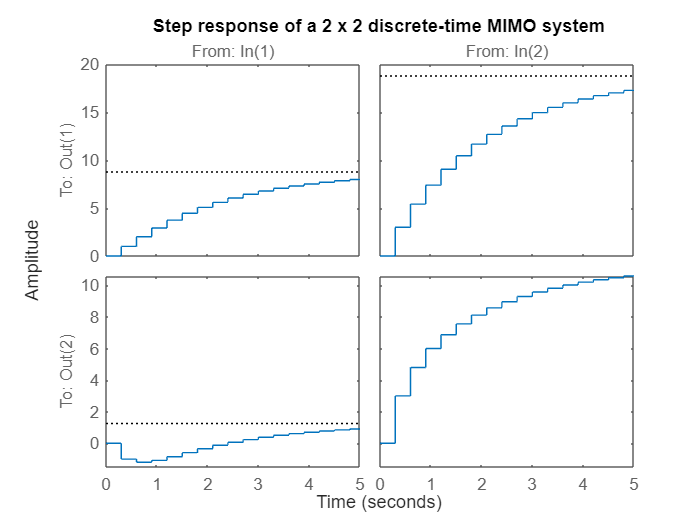

A=[0.8 0.1;0.2 0.5];B=[1 3;2 0];C=[1 0;1 -1];D=[0 0; 0 0]; Tsamp=0.3;
G=ss(A,B,C,D,Tsamp);  % sampling time set as Tsamp
step(G,5)
title('Step response of a 2 x 2 discrete-time MIMO system')

### 3.5 Overlaying responses and more

To avoid repetition, the reader is referred to the transfer function based file ***step_responses_with_matlab ***for more information on how to use ***step.m*** and create nice plots for reports.

### 4. Unforced response with MATLAB (System response to initial states of state-space model)

This section gives a brief background on unforced response and examples of obtaining unforeced response of a state-space model in MATLAB. To do examples of your own, simply change the numbers/dimensions in the code.

MATLAB has a file ***initial.m***, used to compute the unforced system response to initial state (also called initial condition). 

Consider the state-space model

$\dot{X} =A\;X+B\;U;\;Y=C\;X+D\;U,\;$with state *X*, input *U* and output *Y, *with initial state given by  $X\left(0\right)=X_{0\;}$

The unforced repsponse means $U\left(t\right)=0$, and the solution of the state is given as 


$$X\left(t\right)=e^{\textrm{At}} X_{0\;}$$


$e^{\textrm{At}}$ is a matrix function in time *t*, and is called the state transition matrix.

#### 4.1 Continuous-time example with MATLAB

Consider the linear system with no input:

$\left\lbrack \begin{array}{c}
\dot{\;x_1 } \left(t\right)\\
\dot{\;x_2 } \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
2 & 4\\
-1 & -2
\end{array}\right\rbrack \;\left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)
\end{array}\right\rbrack$ and  the initial condition is given by $\left\lbrack \begin{array}{c}
x_1 \left(0\right)\\
x_2 \left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
-1
\end{array}\right\rbrack$.

disp('Below is Section 4.1')

Below is Section 4.1


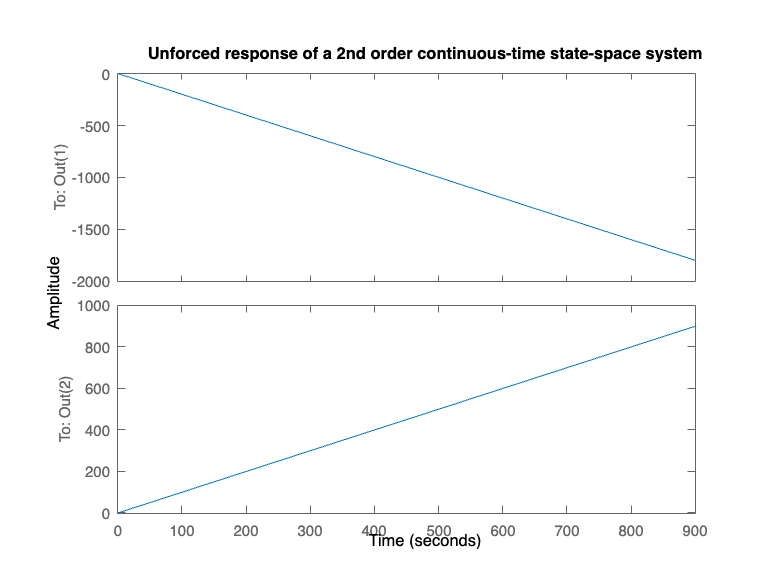

A=[2 4;-1 -2];C=[1 0;0 1]; % C can be chosen differently to see different output response.  
X0=[1;-1];
G=ss(A,[],C,[]);  % create the state-space system without specifying matrices B and D. 
initial(G,X0)
title('Unforced response of a 2nd order continuous-time state-space system')

Consider another example:

$\left\lbrack \begin{array}{c}
\dot{\;x_1 } \left(t\right)\\
\dot{\;x_2 } \left(t\right)\\
\dot{\;x_3 } \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-\frac{1}{3} & 0 & 0\\
0 & -\frac{2}{3} & 0\\
0 & 0 & -1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)\\
x_3 \left(t\right)
\end{array}\right\rbrack$ and the initial condition is given by $\left\lbrack \begin{array}{c}
x_1 \left(0\right)\\
x_2 \left(0\right)\\
x_3 \left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-1\\
-2\\
2
\end{array}\right\rbrack$

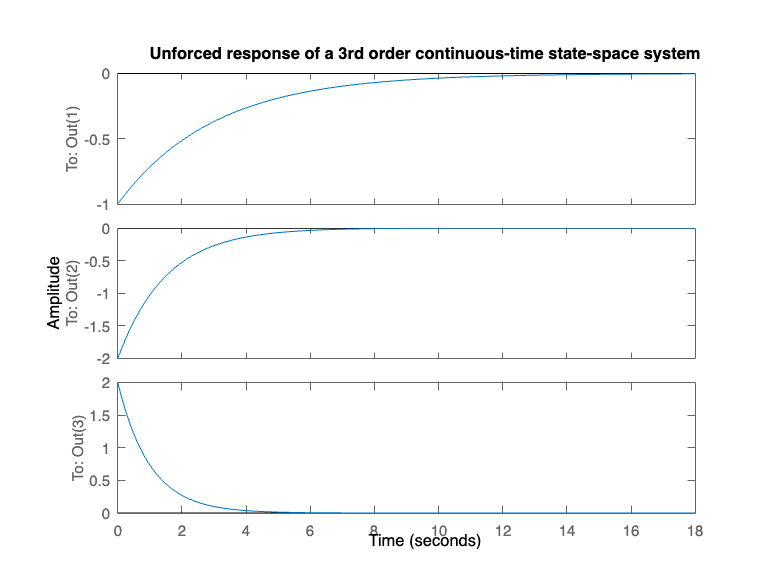

A=[-1/3 0 0;0 -2/3 0;0 0 -1];C=[1 0 0;0 1 0;0 0 1]; % C can be chosen differently to see different output response.  
X0=[-1;-2;2];
G=ss(A,[],C,[]);  % create the state-space system without specifying matrices B and D. 
initial(G,X0)
title('Unforced response of a 3rd order continuous-time state-space system')

#### 4.2 Discrete-time example with MATLAB

Apart from defining the state space model to be discrete, the coding is the same.

disp('Below is Section 4.2')

Below is Section 4.2


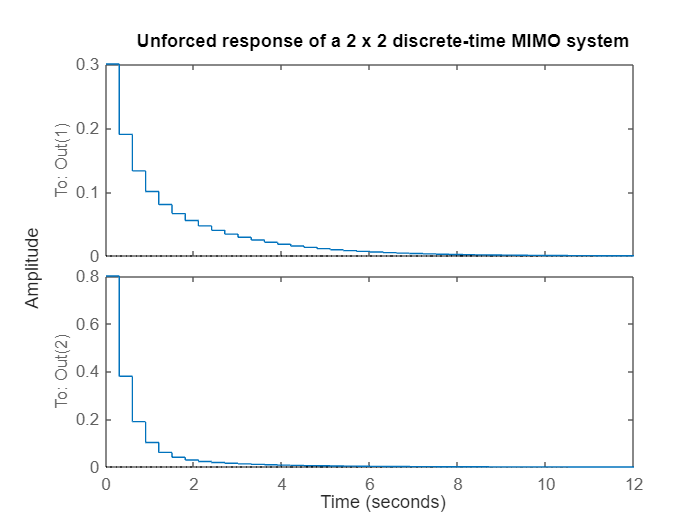

A=[0.8 0.1;0.2 0.5];B=[1 3;2 0];C=[1 0;1 -1];D=[0 0; 0 0]; Tsamp=0.3;
G=ss(A,B,C,D,Tsamp);  % sampling time set as Tsamp
X0=[0.3;-0.5];
initial(G,X0)
title('Unforced response of a 2 x 2 discrete-time MIMO system')

## 5. Forced response with MATLAB (System response to arbitrary input of state-space model)

This section gives a brief background on forced response and  examples of simulating foreced response of a state-space model in MATLAB. To do examples of your own, simply change the numbers/dimensions in the code.

MATLAB has a file ***lsim.m***, used to simulate time response of dynamic systems to arbitrary inputs. 

The forced system with zero initial condition is

$\dot{X} =A\;X+B\;U\;\;$with  $X\left(0\right)=0$. Take Laplace transforms of every element in this model, thus:


$$s\;X\left(s\right)=A\;X\left(s\right)+B\;U\left(s\right)\;$$


Rearranging to solve for first X(s) and then Y(s) gives:


$$X\left(s\right)={\left\lbrack s\;I-A\right\rbrack }^{-1} B\;U\left(s\right)$$


Taking inverse Laplace transforms gives the solution of state in time domain:

$X\left(t\right)={\mathcal{L}}^{-1} \left\lbrace {\left\lbrack s\;I-A\right\rbrack }^{-1} B\;U\left(s\right)\right\rbrace =\int_0^t e^{A\left(t-\tau \;\right)} \textrm{Bu}\left(\tau \;\right)d\tau \;$.

Consider the continuous-time state-space system 


$$A=\left\lbrack \begin{array}{cc}
0 & 1\\
-1 & -0\ldotp 5
\end{array}\right\rbrack \;,B=\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack ,C=\left\lbrack \begin{array}{cc}
0 & 1
\end{array}\right\rbrack ,D=0$$


we focus on the forced response assuming zero initial state $X_0 =0$.

disp('Below is Section 5.1')

Below is Section 5.1


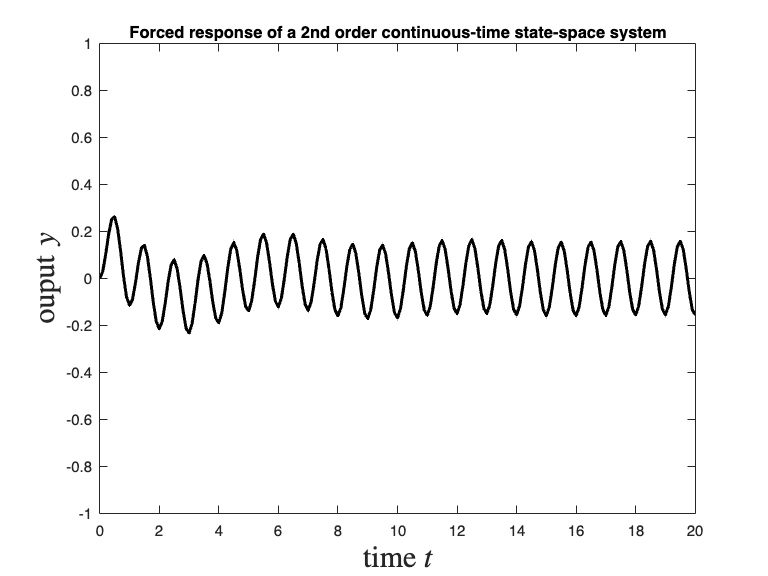

A=[0 1;-1 -0.5]; B=[0;1]; C=[0 1];D=0; 
G=ss(A,B,C,D);    % create the state-space system 
X0=[0;0];         % zero initial condition 

tvec=(0:0.1:20)'; % t goes from 0 to 20 in steps of 0.1
uvec=sin(2*pi*tvec);   % create an sinesiodal input vector 

y = lsim(G,uvec,tvec,X0);   % Returns the system response y, sampled at the same times t as the input.
plot(tvec,y,'k','LineWidth',2); 
axis([0 20 -1 1]);  % set axis limits 
xlabel('time $t$','interpreter','latex','FontSize',20); 
ylabel('output $y$','interpreter','latex','FontSize',20);
title('Forced response of a 2nd order continuous-time state-space system')

**Remark:** Users can use the insights from sections 3.4 and 4.2 to extend this to discrete systems very quickly.

## 6. General response with MATLAB

The general solution of a linear system is the sum of unforced and forced responses. Consider the state-space model

$\dot{X} =A\;X+B\;U;\;Y=C\;X+D\;U,\;$with state *X*, input *U* and output *Y, *with initial state given by  $X\left(0\right)=X_{0\;}$

The general solution of the state is given by


$$X\left(t\right)=e^{\textrm{At}} X_0 +\int_0^t e^{A\left(t-\tau \;\right)} \textrm{Bu}\left(\tau \;\right)d\tau \;$$


Consider the general step response of the following example

$\left\lbrack \begin{array}{c}
\dot{\;x_1 } \left(t\right)\\
\dot{\;x_2 } \left(t\right)\\
\dot{\;x_3 } \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-\frac{1}{3} & 0 & 0\\
0 & -\frac{2}{3} & 0\\
0 & 0 & -1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)\\
x_3 \left(t\right)
\end{array}\right\rbrack$+$\left\lbrack \begin{array}{c}
1\\
1\\
1
\end{array}\right\rbrack U\left(t\right)$ and  the initial condition is given by $\left\lbrack \begin{array}{c}
x_1 \left(0\right)\\
x_2 \left(0\right)\\
x_3 \left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-1\\
-2\\
2
\end{array}\right\rbrack$

disp('Below is Section 6')

Below is Section 6


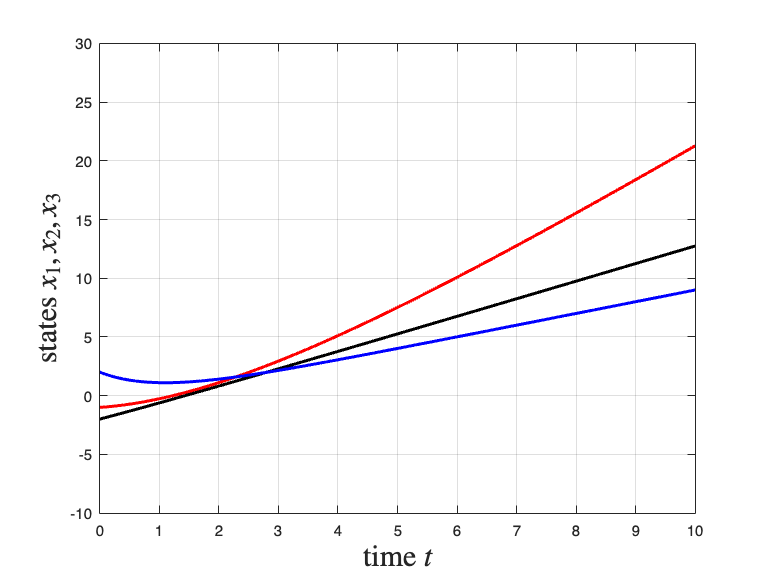

A=[-1/3 0 0;0 -2/3 0;0 0 -1]; B=[1;1;1]; C=eye(3); D=0; 
G=ss(A,B,C,D);    % create the state-space system 
X0=[-1;-2;2];         % set the initial condition 

tvec=(0:0.1:10)'; % t goes from 0 to 10 in steps of 0.1
uvec=1*tvec;      % step input

% Simulate the system 
[y,t,x] = lsim(G,uvec,tvec,X0);   % compute states x % Plot both states (nicely) 
plot(tvec,x(:,1),'r','LineWidth',2); grid on; hold on; 
plot(tvec,x(:,2),'k','LineWidth',2); grid on; hold on; 
plot(tvec,x(:,3),'b','LineWidth',2); grid on; hold on; 
axis([0 10 -10 30]);  % set axis limits 
xlabel('time $t$','interpreter','latex','FontSize',20); 
ylabel('states $x_1,x_2,x_3$','interpreter','latex','FontSize',20);

**Remark:** Users can use the insights from sections 3.4 and 4.2 to extend this to discrete systems very quickly.